# FMCW Radar Model

## Introduction

The purpose of this script is to model a Frequency-Modulated Continuous Wave (FMCW) radar, specifically the AWR2944 radar transceiver on the AWR2944 EVM evaluation board.

The model will consist of the following parts:

- Radar transceiver

- Radar environment

- Data processing

The main purpose of this model is to evaluate different data processing techniques. Thus, the other parts will be simplified to reduce complexity.

clear
clc

## Radar transceiver

The `radarTransceiver` System object will be used to model the radar transceiver. Only monostatic radar transceivers can be modelled this way, meaning that the transmitter and receiver are located at the same point.

The following elements of the transceiver are modelled:

- Waveform

- Transmitter

- Transmit Antenna

- Receive Antenna

- Receiver

For more info on `radarTransceiver` see [link](https://nl.mathworks.com/help/radar/ref/radartransceiver-system-object.html).

### Waveform

The transmitted waveform is a linear chirp from 76 GHz to 81 GHz. This signal will be continuously transmitted with a pulse time of 40  us. See [datasheet](https://www.ti.com/lit/ds/symlink/awr2944.pdf?ts=1696424012463&ref_url=https%253A%252F%252Fwww.ti.com%252Fproduct%252FAWR2944#page=40) section 7.8.

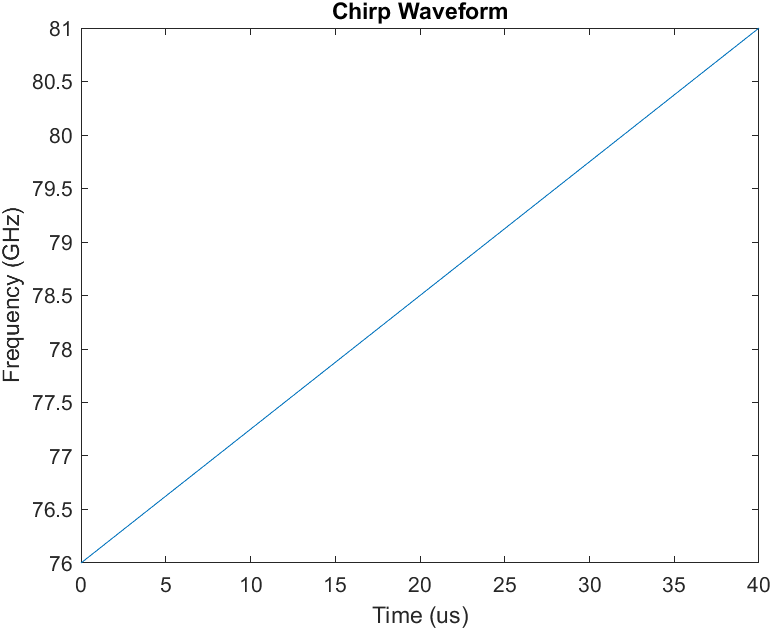

fs = 200e9;
RF.StartFreq = 76e9;
RF.Bandwidth = 5e9;
RF.PulseTime = 40e-6;
RF.PRF = 1/(RF.PulseTime); % Pulse repetition frequency
RF.Waveform = phased.LinearFMWaveform('SampleRate',fs,'PulseWidth',RF.PulseTime, ...
    'PRF',RF.PRF,'SweepBandwidth',RF.Bandwidth,'FrequencyOffset',RF.StartFreq);

The maximum object detection distance can be calculated as a function of the chirp slope and the maximum IF bandwidth (see [datasheet](https://www.ti.com/lit/ds/symlink/awr2944.pdf?ts=1696424012463&ref_url=https%253A%252F%252Fwww.ti.com%252Fproduct%252FAWR2944#page=40) section 7.8) with the following formula:$\frac{B_{\textrm{IF}} *c}{2{\textrm{rate}}_{\textrm{chirp}} }$.

IF.Bandwidth = 15e6;
RF.Slope = RF.Bandwidth/RF.PulseTime;
maxObstacleDistance = IF.Bandwidth*physconst('LightSpeed')/(2*RF.Slope)

maxObstacleDistance = 17.9875

Plot spectrogram of chirp model.

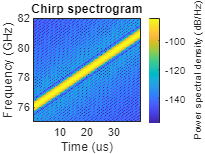

spect.wave = RF.Waveform();
spect.window = hamming(1024);
spect.nov = floor(numel(spect.window)*0.5);
spect.nfft = numel(spect.window)*8;
[~, spect.f, spect.t, spect.pow] = spectrogram(spect.wave,...
    spect.window, spect.nov, spect.nfft, fs);

imagesc(spect.t*1e6, spect.f*1e-9, pow2db(spect.pow+eps)) % add eps to avoid error
axis xy
xlabel("Time (us)")
ylabel("Frequency (GHz)")
ylim([75 82])
spect.c = colorbar;
spect.c.Label.String = 'Power spectral density (dB/Hz)';
title("Chirp spectrogram")

### Transmitter

Only the peak power of the transmitter is modelled. Gain and phase noise aren't modelled. See the [AWR2944 datasheet](https://www.ti.com/lit/ds/symlink/awr2944.pdf?ts=1696424012463&ref_url=https%253A%252F%252Fwww.ti.com%252Fproduct%252FAWR2944#page=40) section 7.8.

TX.PeakPower = 13.5; %dBm
% TX.Transmitter = phased.Transmitter('PeakPower', 10^((TX.PeakPower-30)/10));
TX.Transmitter = phased.Transmitter;

### Antenna

The same custom antenna design is used for both the transmit and receive antenna. See [EVM User's Guide](https://www.ti.com/lit/ug/spruj22a/spruj22a.pdf?ts=1696405245404&ref_url=https%253A%252F%252Fwww.ti.com%252Ftool%252FAWR2944EVM).

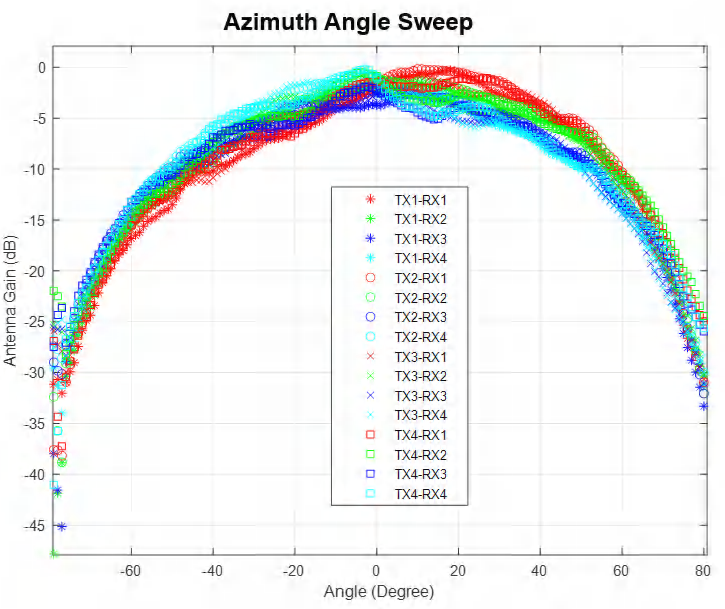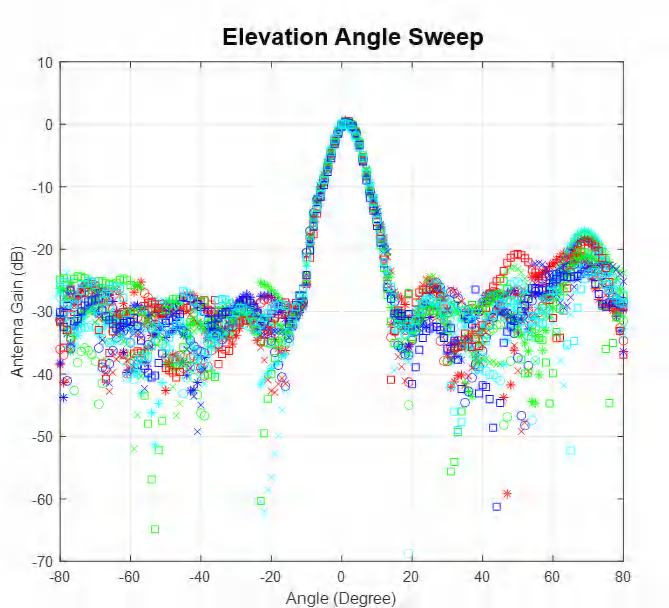

Antenna.AzAngles = -180:10:180; % specify full azimuth and elevation range to avoid interpolation error
Antenna.ElAngles = -90:5:90;

Antenna.AzPattern(1:11) = -inf;
Antenna.AzPattern(12:26) = [-23 -17 -13.5 -10 -7.5 -6 -4 -2 -4 -6 -7.5 -10 -13.5 -17 -23];
Antenna.AzPattern(27:37) = -inf;
Antenna.ElPattern(1:15)= -inf;
Antenna.ElPattern(16:22) = [-30 -25 -13 0 -13 -25 -30];
Antenna.ElPattern(23:37) = -inf;

Convert 2 2D cuts into a 3D pattern.

Antenna.MagPattern = azelcut2pat(Antenna.AzPattern, Antenna.ElPattern);
Antenna.PhasePattern = zeros(size(Antenna.MagPattern));

**Add plot of 2D cuts**

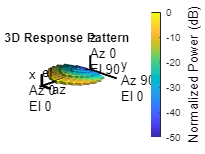

Antenna.DisplayAntenna = phased.CustomAntennaElement('AzimuthAngles',Antenna.AzAngles,'ElevationAngles',...
    Antenna.ElAngles,'MagnitudePattern',Antenna.MagPattern,'PhasePattern',Antenna.PhasePattern);
pattern(Antenna.DisplayAntenna, 1e9, -180:180, -90:90, 'Type', 'powerdb')

release(Antenna.DisplayAntenna)

### Transmit Antenna

The model for the transmit antenna contains only a single element. Antenna gain isn't modelled.

TX_Antenna.Element = phased.IsotropicAntennaElement;
% TX_Antenna.Element = phased.CustomAntennaElement('AzimuthAngles',Antenna.AzAngles,'ElevationAngles',...
%     Antenna.ElAngles,'MagnitudePattern',Antenna.MagPattern,'PhasePattern',Antenna.PhasePattern);
TX_Antenna.Antenna = phased.Radiator('Sensor', TX_Antenna.Element);

### Receive Antenna

The model for the transmit antenna contains only a single element. Antenna gain isn't modelled.

RX_Antenna.Element = phased.IsotropicAntennaElement;
% RX_Antenna.Element = phased.CustomAntennaElement('AzimuthAngles',Antenna.AzAngles,'ElevationAngles',...
%     Antenna.ElAngles,'MagnitudePattern',Antenna.MagPattern,'PhasePattern',Antenna.PhasePattern);
RX_Antenna.Antenna = phased.Collector('Sensor', RX_Antenna.Element);

### Receiver

Receiver gain and noise are modelled in the receiver. The noise temperature method is used to model the noise.

RX.Gain = 44; %dB
RX.NoiseFigure = 12; %dB
% RX.NoiseFigure = 0; %dB
RX.SampleRate = fs;
RX.Receiver = phased.ReceiverPreamp('Gain',RX.Gain,'NoiseFigure', ...
    RX.NoiseFigure,'SampleRate',RX.SampleRate);

### Transceiver

Transceiver = radarTransceiver('Waveform',RF.Waveform,'Transmitter',TX.Transmitter,...
    'TransmitAntenna',TX_Antenna.Antenna,'ReceiveAntenna',RX_Antenna.Antenna,...
    'Receiver',RX.Receiver);
release(RF.Waveform)
release(TX_Antenna.Antenna)
release(RX_Antenna.Antenna)

## Radar environment

The radar environment models the object(s) to be detected by the radar. The transceiver from the previous section is used to generate the appropriate received signal.

### Radar target

A single static target is used at a distance of 10 meters along the X axis.

tgt.Position = [1 0 0];
tgt.Velocity = [0 0 0];

### Simulation

Simulate single chirp transmission (40us).

RX_RF.wave = Transceiver(tgt, 0);
RX_RF.window = hamming(1024);
RX_RF.nov = floor(numel(RX_RF.window)*0.5);
RX_RF.nfft = numel(RX_RF.window)*8;
[~, RX_RF.f, RX_RF.t, RX_RF.pow] = spectrogram(RX_RF.wave,...
    RX_RF.window, RX_RF.nov, RX_RF.nfft, fs);

Plot spectrogram of received signal.

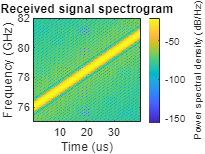

imagesc(RX_RF.t*1e6, RX_RF.f*1e-9, pow2db(RX_RF.pow+eps)) % add eps to avoid error
axis xy
xlabel("Time (us)")
ylabel("Frequency (GHz)")
ylim([75 82])
RX_RF.c = colorbar;
RX_RF.c.Label.String = 'Power spectral density (dB/Hz)';
title("Received signal spectrogram")

## Radar Transceiver (IF)

Use frequency mixer with transmitted and received signal to generate IF (Intermediate Frequency) signal.

TX_RF.wave = RF.Waveform();
IF.wave = dechirp(RX_RF.wave, TX_RF.wave);

Decimate IF signal to ADC sampling rate 37.5MS/s (see [datasheet](https://www.ti.com/lit/ds/symlink/awr2944.pdf?ts=1696424012463&ref_url=https%253A%252F%252Fwww.ti.com%252Fproduct%252FAWR2944#page=40) section 7.8).

IF_fs = 37.5e6;
decimationFactor = ceil(fs/IF_fs);
IF.wave = decimate(IF.wave, decimationFactor);

Plot spectrogram of IF signal.

OPTIMIZE SPECTROGRAM

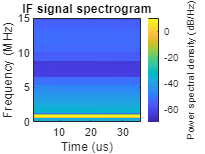

IF.window = hamming(256);
IF.nov = floor(numel(IF.window)*0.5);
IF.nfft = numel(IF.window)*8;
[~, IF.f, IF.t, IF.pow] = spectrogram(IF.wave,...
    IF.window, IF.nov, IF.nfft, fs/decimationFactor);

imagesc(IF.t*1e6, IF.f*1e-6, pow2db(IF.pow+eps)) % add eps to avoid error
axis xy
xlabel("Time (us)")
ylabel("Frequency (MHz)")
ylim([0 15])
IF.c = colorbar;
IF.c.Label.String = 'Power spectral density (dB/Hz)';
title("IF signal spectrogram")   

## Date Processing

The purpose of the data processing section is to calculate properties of the object. For now this only includes the distance of the object to the radar.

### FFT

The first step is to perform an FFT on the input data to get the frequency information.

dsp.fft = fft(IF.wave);
dsp.size = numel(dsp.fft);
dsp.f = IF_fs/dsp.size*(0:dsp.size-1);

The frequency of the input data is plotted.

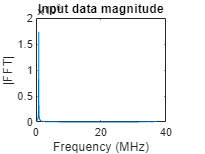

plot(dsp.f*1e-6, abs(dsp.fft))
xlabel("Frequency (MHz)")
ylabel("|FFT|")
title("Input data magnitude")

### Peak finding

The next step is to find the peak in the FFT to identify the frequency of the signal.

[~, maxIndex] = max(abs(dsp.fft));
maxFreq = dsp.f(maxIndex);

### Distance calculation

With the frequency of the signal the distance of the object can be calculated with the following formula: $d=\frac{f_{\textrm{IF}} *c}{2{\textrm{rate}}_{\textrm{chirp}} }$

distance = maxFreq*physconst('LightSpeed')/(2*RF.Slope)

distance = 0.9893